# 

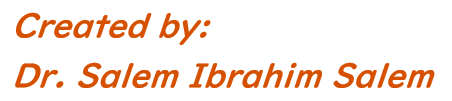

**Student Name(In English)**: Andreiev Maksym

**Student ID**: 2022m666

# **Assignment No. (12)**

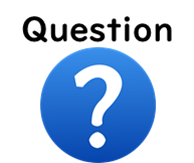

***Q1. *** The attached Excel file "**Students_Data.xlsx**" has two spreadsheets as follows:

- "**Grade**" spreadsheet: that contains the assignments' grades of 10 students for 15 weeks. The top score for each assignment is 100 point.

- "**Attendance**" spreadsheet: that contains the attendance of 10 students for 15 weeks. "1" means attend and "0" means absent. 

***Requirement*** 

- Import the "week" column from the "**Grade**" spreadsheet as a column vector with the name "**week**". 

- Import "students grades" columns from the "**Grade**" spreadsheet as a matrix with the name "**Grades**". *Replace missing grade with "zero".*

- Calculate the whole mean grade of all students. 

- Count how many times students got grades greater or equal to the whole mean grade.

- Import "students attendance" columns from the "**Attendance**" spreadsheet as a matrix with the name "**Attendance**". *Replace missing grade with "zero".*

- Calculate the summation of attendance for each student.

- Count the number of students who attended the 15 weeks.

week = readmatrix("Students_Data.xlsx", "Sheet", "Grade", "Range", "A2:A16");
students_grades = readmatrix("Students_Data.xlsx", "Sheet","Grade", "Range", "B2:K16");
students_grades(isnan(students_grades)) = 0;
wh_mean = mean(students_grades, "all")

wh_mean = 73.6933

count_ = numel(students_grades(students_grades > wh_mean))  % I use boolean mask to the array of all grades and then count them

count_ = 79

students_attendance = readmatrix("Students_Data.xlsx", "Sheet", "Attendance", "Range", "B2:K16");
students_attendance(isnan(students_attendance)) = 0;
att_of_each = sum(students_attendance)

att_of_each =     13    14    14    14    14    14    13    15    15    12


numel(att_of_each(att_of_each == 15))

ans = 2